# Edit Plots

Matlab makes me mad :(

This just makes a good figure out of the fval plot from the optimization in `TestInverseDesign.mlx `because I can't figure out how to edit it beforehand. 

Honestly I still can't figure it out. I just took a screenshot of the plot because idk how to save it.

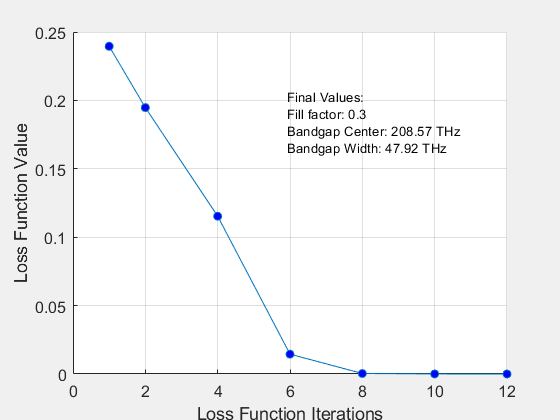

% Read figure
fig = openfig('figures/fval-plot.fig');

% Get data from figure
dataObject = get(gca, 'Children');
x_data = get(dataObject, 'Xdata');
y_data = get(dataObject, 'Ydata');

% Data gathered from running TestInverseDesign.mlx
fontsize = 12;
func_count = [1, 2, 4, 6, 8, 10, 12];

% Edit figure
plot(func_count, y_data, '-o', 'MarkerFaceColor', 'b')
grid on;
title('');
xlabel('Loss Function Iterations');
ylabel('Loss Function Value');
set(gca, 'FontSize', fontsize)

% Add bandgap details also from TestInverseDesign.mlx
annotation('textbox', [.5 .5 .4 .3], 'String', ...
    ['Final Values:' newline 'Fill factor: 0.3' newline 'Bandgap Center: 208.57 THz' newline 'Bandgap Width: 47.92 THz'], ...
    'EdgeColor', 'none' ...
)

fig.Visible = 'on';